if exist("wcli", "var")
    clib.webcface.wcfClose(wcli);
end

clear all;
close all;

webcfaceのロードと初期化

addpath("./webcface")
configObj = clibConfiguration("webcface", ExecutionMode="outofprocess")

configObj =  プロパティをもつ webcface の CLibraryConfiguration:

    InterfaceLibraryPath: "C:\Users\mech-user\3a_pro\ik\webcface\webcfaceInterface.dll"
               Libraries: ["webcface.dll"    "spdlogd.dll"]
                  Loaded: 1
           ExecutionMode: outofprocess
               ProcessID: 16432


wcli = clib.webcface.wcfInit("matlab-test", "127.0.0.1", 7530);
clib.webcface.wcfStart(wcli);

fk, ikの初期化

% Generate robot
%robot = loadrobot("kinovaGen3","DataFormat","column");
robot = importrobot("robot.urdf");
q = homeConfiguration(robot);
dof = length(q);

p0 = tform2trvec(getTransform(robot, q, "arm_link7_link", "base_link"));
x0 = p0(1)

x0 = 0.5084

y0 = p0(2)

y0 = -0.0300

z0 = p0(3)

z0 = 0.2976


% Define IK solver
ik = inverseKinematics('RigidBodyTree', robot);
weights = [0, 0, 0, 1, 1, 1];
%weights = [1, 1, 1, 1, 1, 1];
endEffector = 'arm_link7_link';

初期状態にする (ボタンを押すと実行)

 
q = homeConfiguration(robot);
qs = ["0" "0" "0" "0" "0" "0" "0"];
reverse = [1 1 1 -1 1 -1 1];
for j = 1:7
    % radをdegにし、±150度を0～1023にする
    qs(j) = num2str(floor(rad2deg(q(j).JointPosition) * reverse(j) / 300 * 1023 + 500));
end
clib.webcface.wcfFuncRunS(wcli, "bullet-sim", "move_servo", qs)

ans = ""

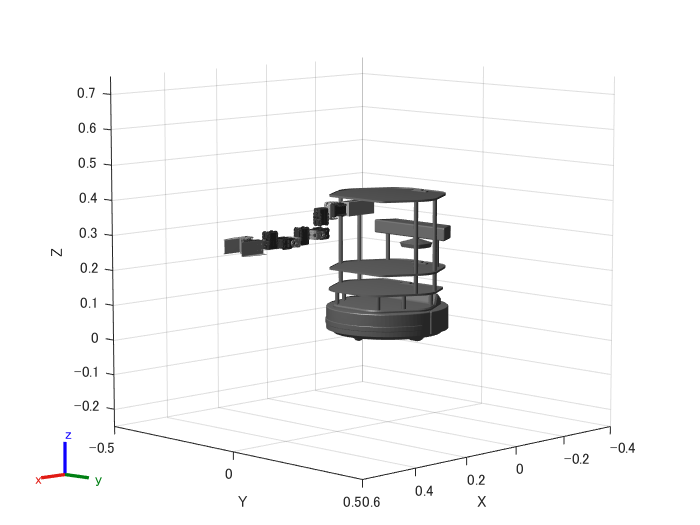

show(robot, q, Frames="off");
xlim([-0.4 0.6])
ylim([-0.5 0.5])
zlim([-0.25 0.75])

値を入れてikを解き、送る

x = 0.41

x = 0.4100

y = 0.5

y = 0.5000

z = 0.43

z = 0.4300

q = ik(endEffector,trvec2tform([x y z]),weights,q);
qs = ["0" "0" "0" "0" "0" "0" "0"];
for j = 1:7
    % radをdegにし、±150度を0～1023にする
    % todo: 小数渡すとエラー出すので整数にしているがあとでなおす
    qs(j) = num2str(floor(rad2deg(q(j).JointPosition) * reverse(j) / 300 * 1023 + 500));
end
clib.webcface.wcfFuncRunS(wcli, "bullet-sim", "move_servo", qs)

ans = ""

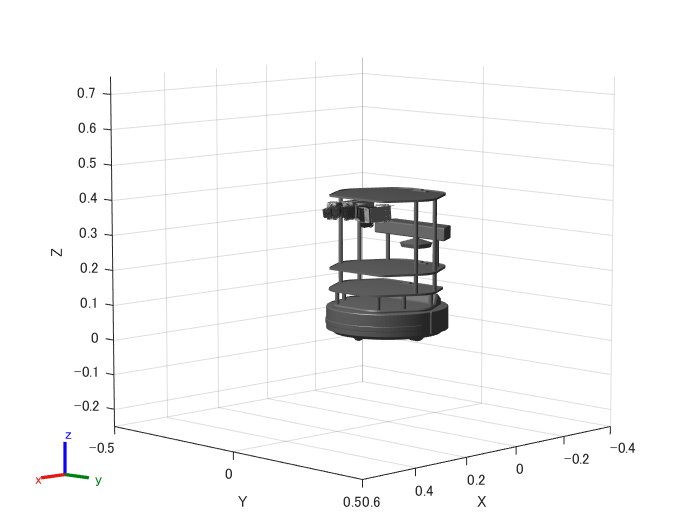

show(robot, q, Frames="off");
xlim([-0.4 0.6])
ylim([-0.5 0.5])
zlim([-0.25 0.75])

サーボをoffにする

 
clib.webcface.wcfFuncRunS(wcli, "dynamixel", "free_servo", [])

ans = ""